# ROZWIĄZYWANIE RÓWNAŃ NIELINIOWYCH

## WŁAŚCIWOŚCI METODY NEWTONA I METOD POCHODNYCH

Tym razem skupimy się na właściwościach metody Newtona i metod pochodnych. Po pierwsze na podstawie przeprowadzonej na zajęciach analizy może dziwić, że metoda siecznych ma współczynnik zbieżności będący liczbą niecałkowitą. Zobaczmy najpierw czy rzeczywiście tak jest. Jeżeli tak to zależność błędu w kolejnych iteracjach powinna być wolniejsza niż dla metody Newtona, ale znacznie szybsza niż dla metody *regula falsi*.

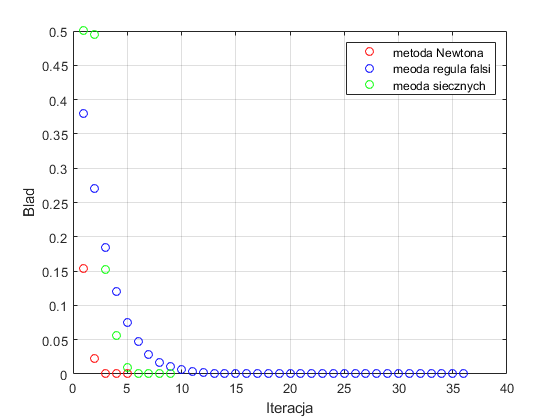

% Do rozwiązania przyjmiemy prostą funkcję o oczywistym rozwiązaniu
% teoretycznym
f = @(x) (x-1).*(x-2).*(x-5);
df = @(x) (x - 1).*(x - 2) + (x - 1).*(x - 5) + (x - 2).*(x - 5);
true_root = 1;
% Pierwszy testy wykonamy dla metody bisekcji
options.imax = 100;    %w ten sposób ustawiamy maksymalna ilość iteracji
options.return_all = true;  % ta flaga powoduje zwrócenie wyników pośrednich w kolejnych iteracjach
options.TOL = 1e-8; % zakładana dokładność
options.warnings = true; % dostaniemy warning w przypadku jakby coś poszło nie tak

% Ustalamy włąściewe warunki startowe dla metody Newtona
a = 0;
b = 1.5;
x0 = 0.5;
% Uruchamiamy implementację metody Newtona
[resultsNewton] = calculateNewtonSolution(f,df,x0,options);
errorNewton = abs(resultsNewton - true_root);
plot(errorNewton, 'ro'); xlabel('Iteracja'); ylabel('Blad'); grid on;hold on;

% Powtarzamy procedurę dla metody regula falsi
[resultsFalsePosition] = calculateFalsePositionSolution(f,a,b,options);
errorFalsePosition = abs(resultsFalsePosition - true_root);
plot(errorFalsePosition, 'bo');xlabel('Iteracja'); ylabel('Blad'); grid on;


% Powtarzamy procedurę dla metody siecznych
% Uwaga - zastosowana tutaj implementacja bierze jako drugi punkt metody
% siecznych punkt odległy o 1% (x(2) = 1.01*x0) od punktu x0. Dlaczego
% tak jest dowiemy się przy okazji omawiania sposobów numerycznego
% różniczkowania
[resultsSecant] = calculateSecantSolution(f,x0,options);
errorSecant = abs(resultsSecant - true_root);
plot(errorSecant, 'go');xlabel('Iteracja'); ylabel('Blad'); grid on;hold off;

legend('metoda Newtona', 'metoda regula falsi', 'metoda siecznych');

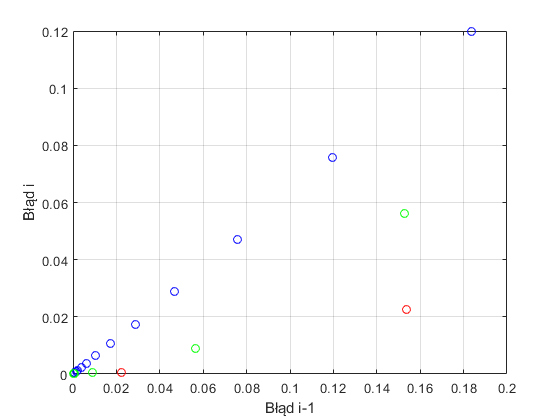


% Drugi wykres zgodny z definicją
oldNewtonError = errorNewton(1:end-1);
newNewtonError = errorNewton(2:end);

plot(oldNewtonError, newNewtonError, 'ro'); hold on;

oldFalsePositionError = errorFalsePosition(1:end-1);
newFalsePositionError = errorFalsePosition(2:end);

plot(oldFalsePositionError, newFalsePositionError, 'bo');xlabel('Błąd i-1'); ylabel('Błąd i'); grid on;

oldSecantError = errorSecant(1:end-1);
newSecantError = errorSecant(2:end);

plot(oldSecantError, newSecantError, 'go');xlabel('Błąd i-1'); ylabel('Błąd i'); grid on;


axis([0 0.2 0 0.12]); hold off;

**ĆWICZENIE 1:**

Mimo, że wszystkie te metody są stworzone w oparciu o modyfikację metody Newtona, to zmiana wzoru iteracyjnego niesie za sobą poważne zmiany właściwości numerycznych. Dotyczy to nie tylko szybkości zbiezności, ale również zakresów zbieżności. Aby to zobaczyć w powyższym kodzie postaraj się dobrać tak punkt startowy $x_0$, żeby metody Newtona i sicznych dawały różne wyniki.

Zastanów się, czy nie jest w takim razie problemem nietrywialnym znalezienie wszystkich pierwiastków równania (zazwyczaj nie znamy wzoru finkcji)?

Niecałkowity wykładnik zbieżności lokalnej z faktu, że metoda siecznych *de facto* wymaga dwóch punktów startowych, a nasza analiza obejmowała tylko najprostszy przypadek metody iteracyjnej jednokkrokowej. W przypadku bardziej skomplikowanych metod wielokrokowych sytuacja komplikje się o tyle, że:

- wykładnik zbieżności może przyjmować wartości niecałkowite

- istotną rolę zaczyna odgrywać położenie kolejnych punktów startowych wzgędem siebie (w dodatku do położenia punktu startowego względem rozwiązania prawdziwego i wfłaściwości funkcji)

**ĆWICZENIE 2:**

Aby zobrazować drugi czynnik uruchamiaj poniższy kod dla różnych położeń punktów startowych w metodzie siecznych i obserwuj wyniki zbieżności. Czy za każdym razem potrafisz wytłumaczyć obserwowane efekty?

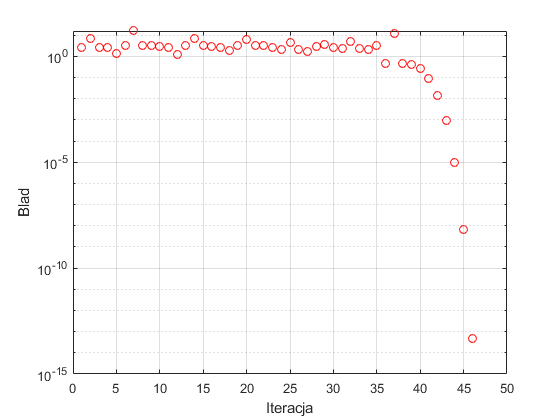

% Przjmijmy inny wielomian jako przykład
f = @(x)x.^3-2.*x+2;

% Ograniczmy ilośc iteracji - PAMIĘTAJ ŻEBY ZAWZSZE OGRANICZAĆ ILOŚĆ
% ITERACJI
options.imax = 100;    %w ten sposób ustawiamy maksymalna ilość iteracji
options.return_all = true;  % ta flaga powoduje zwrócenie wyników pośrednich w kolejnych iteracjach
options.TOL = 1e-8; % zakładana dokładność
options.warnings = true; % dostaniemy warning w przypadku jakby coś poszło nie tak

true_root = fzero(f,-5);

% Uruchamiamy implementację metody Newtona
x0 = 1;
x1 = 5;
[resultsSecant] = calculateSecantSolution2Points(f,x0,x1,options);
errorSecant = abs(resultsSecant - true_root);
semilogy(errorSecant, 'ro'); xlabel('Iteracja'); ylabel('Blad'); grid on;hold off;

Zwróć uwagę, że jest to ten sam przypadek jaki mieliśmy w poprzednim przypadku metody Newtona.